# **IO397 - Analog Loopback**

This example shows you how to use the analog inputs and outputs of the IO397-50k I/O Module.

The IO397 I/O module is a mPCIe-compatible, configurable I/O module and Simulink-programmable FPGA offering 50k logic cells, 4 ADC input channels, 4 DAC output channels, 14 ESD-protected TTL I/O lines and an AMD® Artix®-7 chip. The 4 ADC input channels each have a 16-bit resolution and can work with up to 200 ksps. The analog input circuit is designed to allow software-selectable input voltages of 0-5.12V, 0-10V, 0-10.24V, ±5V, ±5.12V, ±10V and ±10.24V.

The 4 DAC output channels also each offer a 16-bit resolution and a settling time of 10μs. The analog output circuit is designed to allow software-selectable output voltages of 0-5V,v 0-10V, 0-10.8V, ±5V, ±10V or ±10.8V.

This example demonstrates the usage of the above mentioned ADC inputs and DAC outputs. To facilitate a quick startup without additional hardware required, the analog outputs are looped back into the analog inputs.

The Simulink model features a simple demonstration of the analog input and output Simulink blocks. The blocks are setup for a single working point for the analog inputs and outputs though other configurations would work as well.

## Setup

### Prerequisites

You will require the following to run this example:

- Speedgoat real-time target machine with one IO397-50k I/O module installed

- One 17-pin Male M12 to 17-pin female M12 Connector cable from the I/O module to the terminal board

- One 17-pin M12 terminal board with jumper wires

### Connection Diagram

The module terminal board should be wired in a loopback configuration, with analog outputs fed into analog inputs, as shown in the table below:

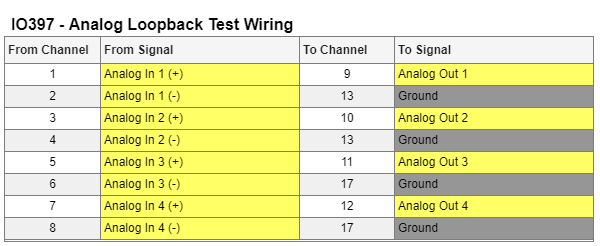

## Initialize and Open the Simulink model

 
% Open Simulink model
modelName = 'sgMdl_IO397_AnalogLoopback';
open_system(modelName);

Before the Simulink model can be built, the I/O module and configuration file must be specified in the IO3xx Setup block, as this example can be executed on different configurable I/O modules. First, open the mask of the IO3xx Setup block and select your I/O module from the drop-down. Once the mask has extended, select a configuration file. This example only requires analog interfaces, which are supported by any configuration file for the IO397 by default.

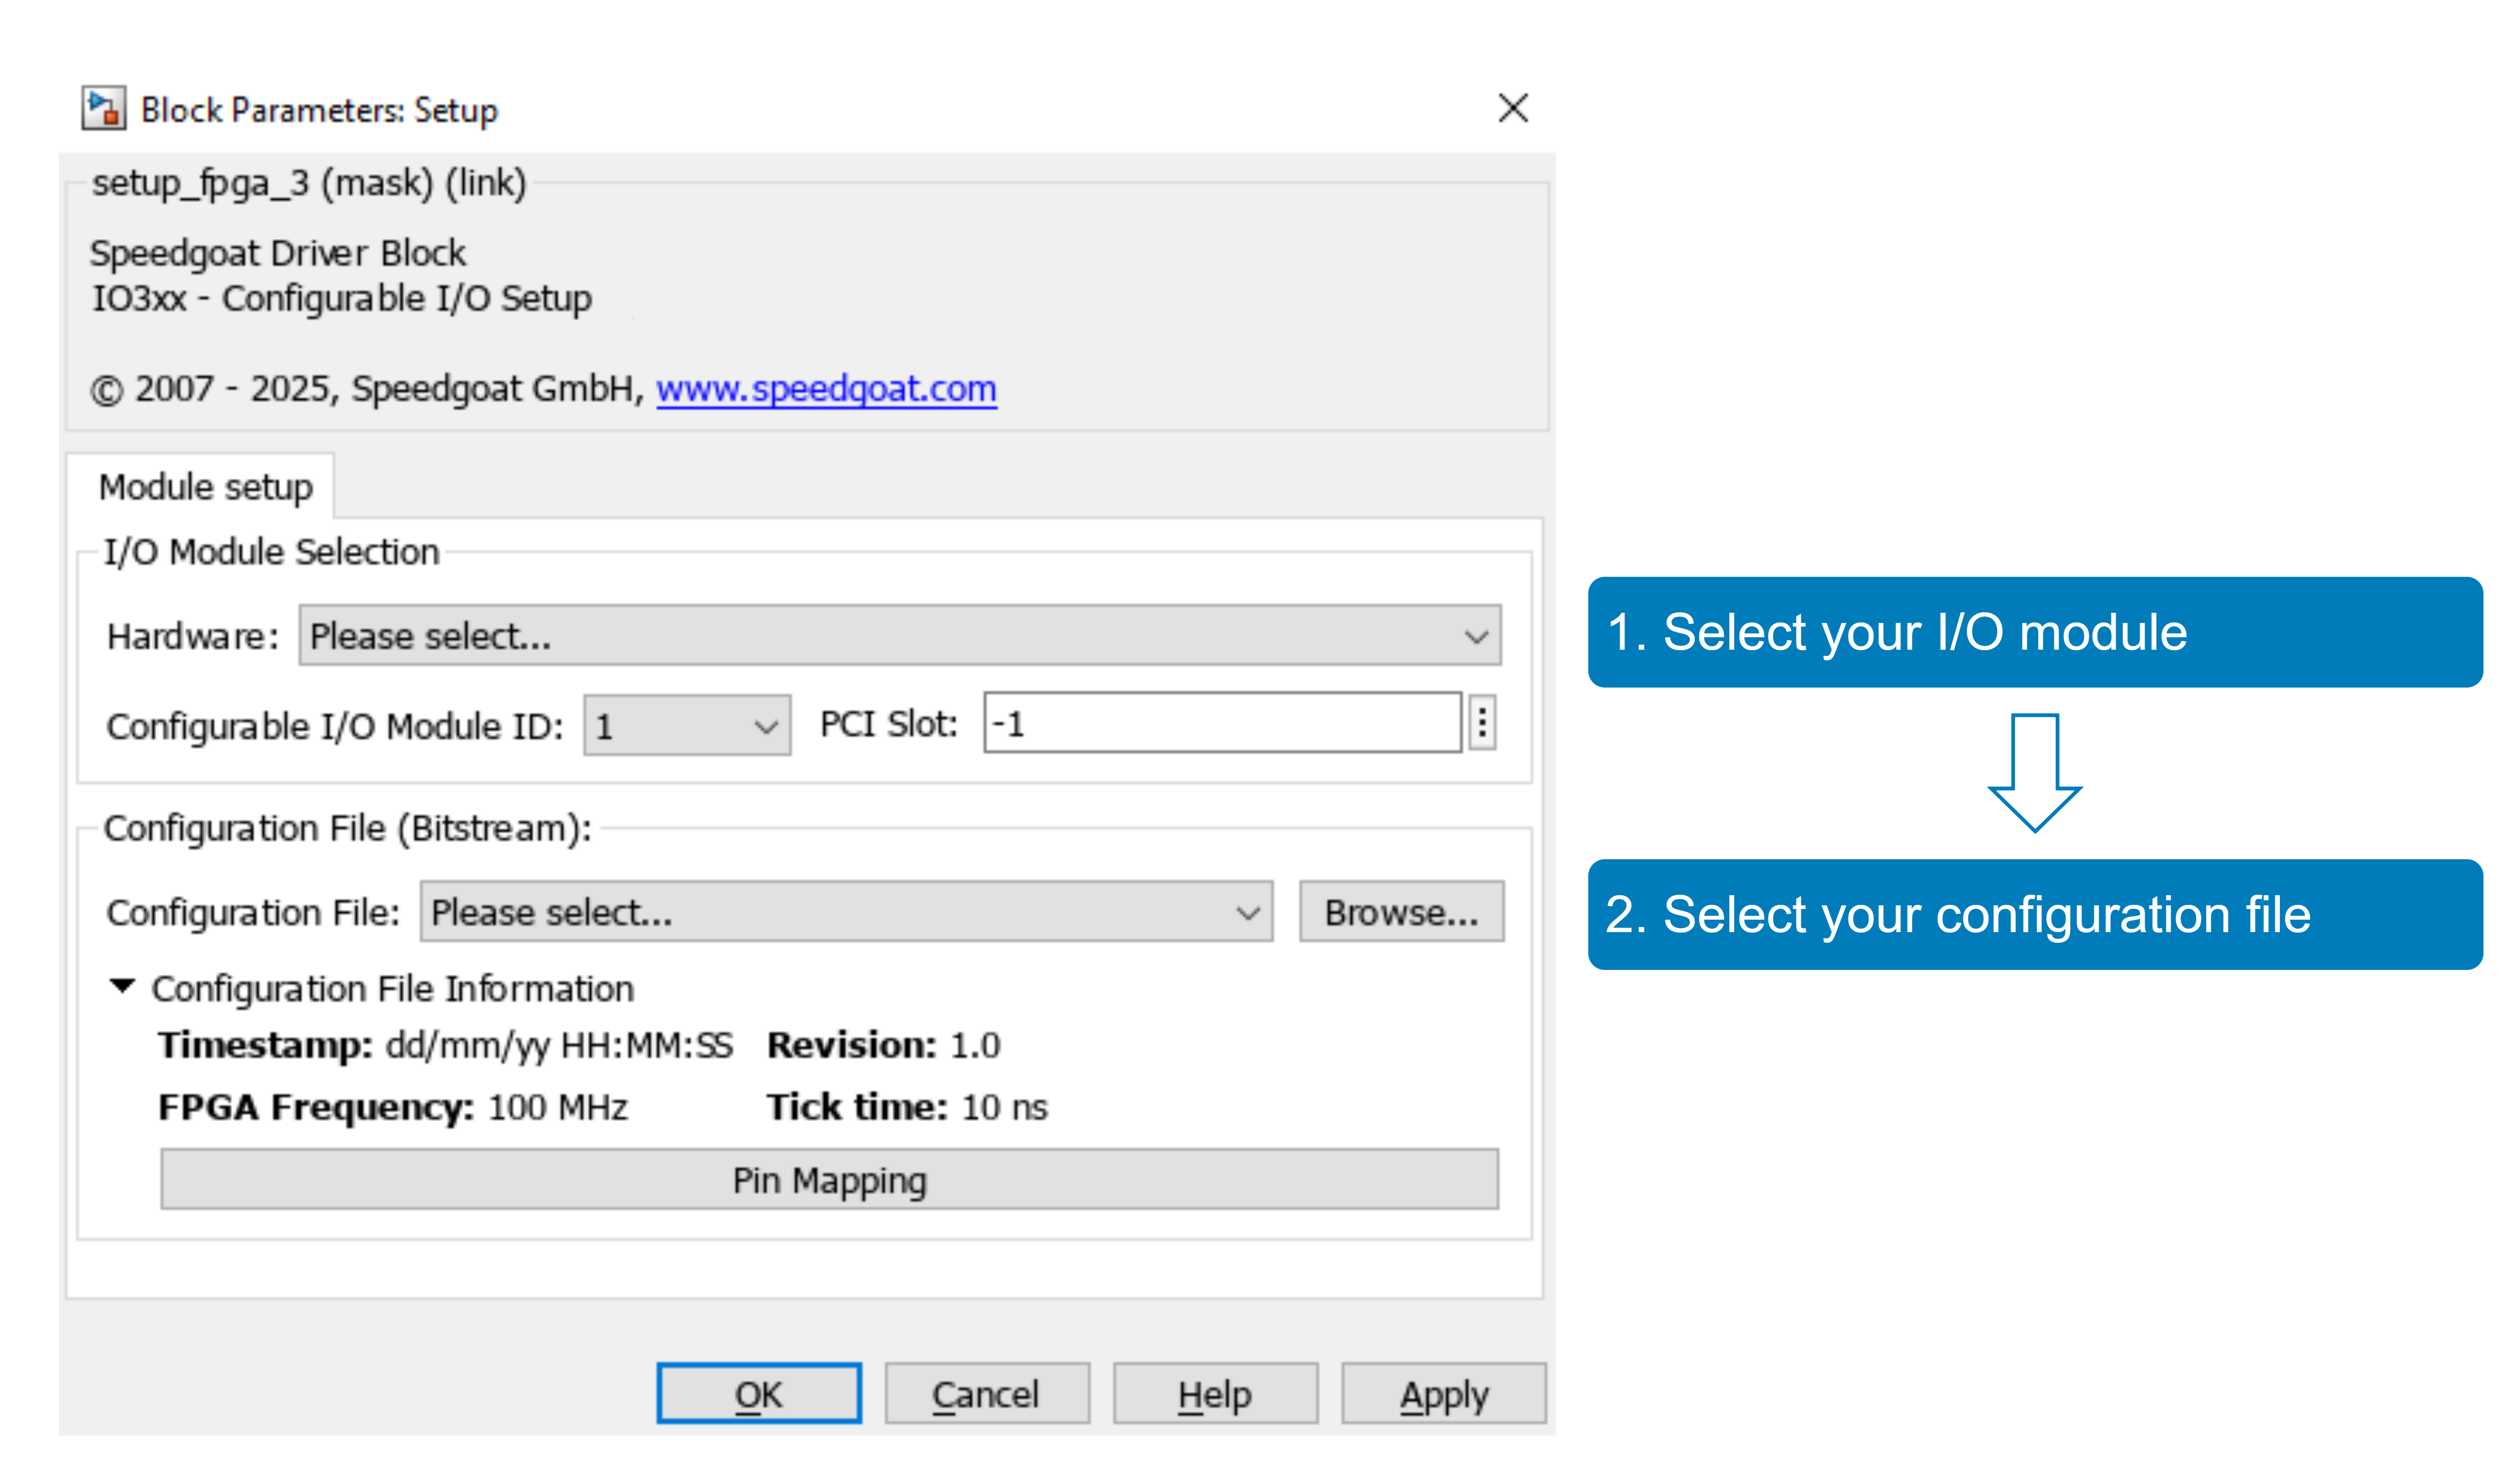

With the **Pin Mapping** button you can now check where the functionalities are located.

### Model Description

In the model, look at the configurations of the D/A Write and A/D read blocks. Note how both the ADC and DAC are configured with compatible ranges: 0-5V and 0-5.12V, respectively. The ADC channels are fully differential. This is why the negative side of the ADC inputs are connected to ground pins on the terminal board, to have the same ground reference as the DACs. The DACs of the module only support single ended signals and are internally ground referenced, requiring no negative side wiring. The signal sources of the D/A write block are simple discreet sine wave sources with a compatible 2.5V amplitude and 2.5V bias, to comply with the pre-configured input voltage range. Feel free to change the ranges and input parameters to get an understanding of the analog capabilities of the module. Incompatible ranges will cause clipping of the signal.

## Build, Download, and Run the Example

To run the example, either run the following code section or click the **Run on Target** button in the **REAL-TIME** tab in the Simulink model.

 
% Build the Simulink model
slbuild(modelName);         % this will create the real-time application file (.mldatx)

% Create and connect to the Speedgoat real-time target machine
tg = slrealtime;            
tg.connect;

% Download and install the real-time application on the target machine
tg.load(modelName); 

% Connect the Simulink model with external mode to the real-time application on the target machine
set_param(modelName,'SimulationMode',   'external')   % put model into External Mode
set_param(modelName,'SimulationCommand','connect')    % connect with External Mode   

% Start the real-time application
tg.start

% Wait a few seconds and then stop the real-time application on the target machine
pause(10)
tg.stop;

### Check the Results

If your wiring is correct, after running the model when you double click the Simulink scope, it should open a window which shows signals that look similar to the image below.

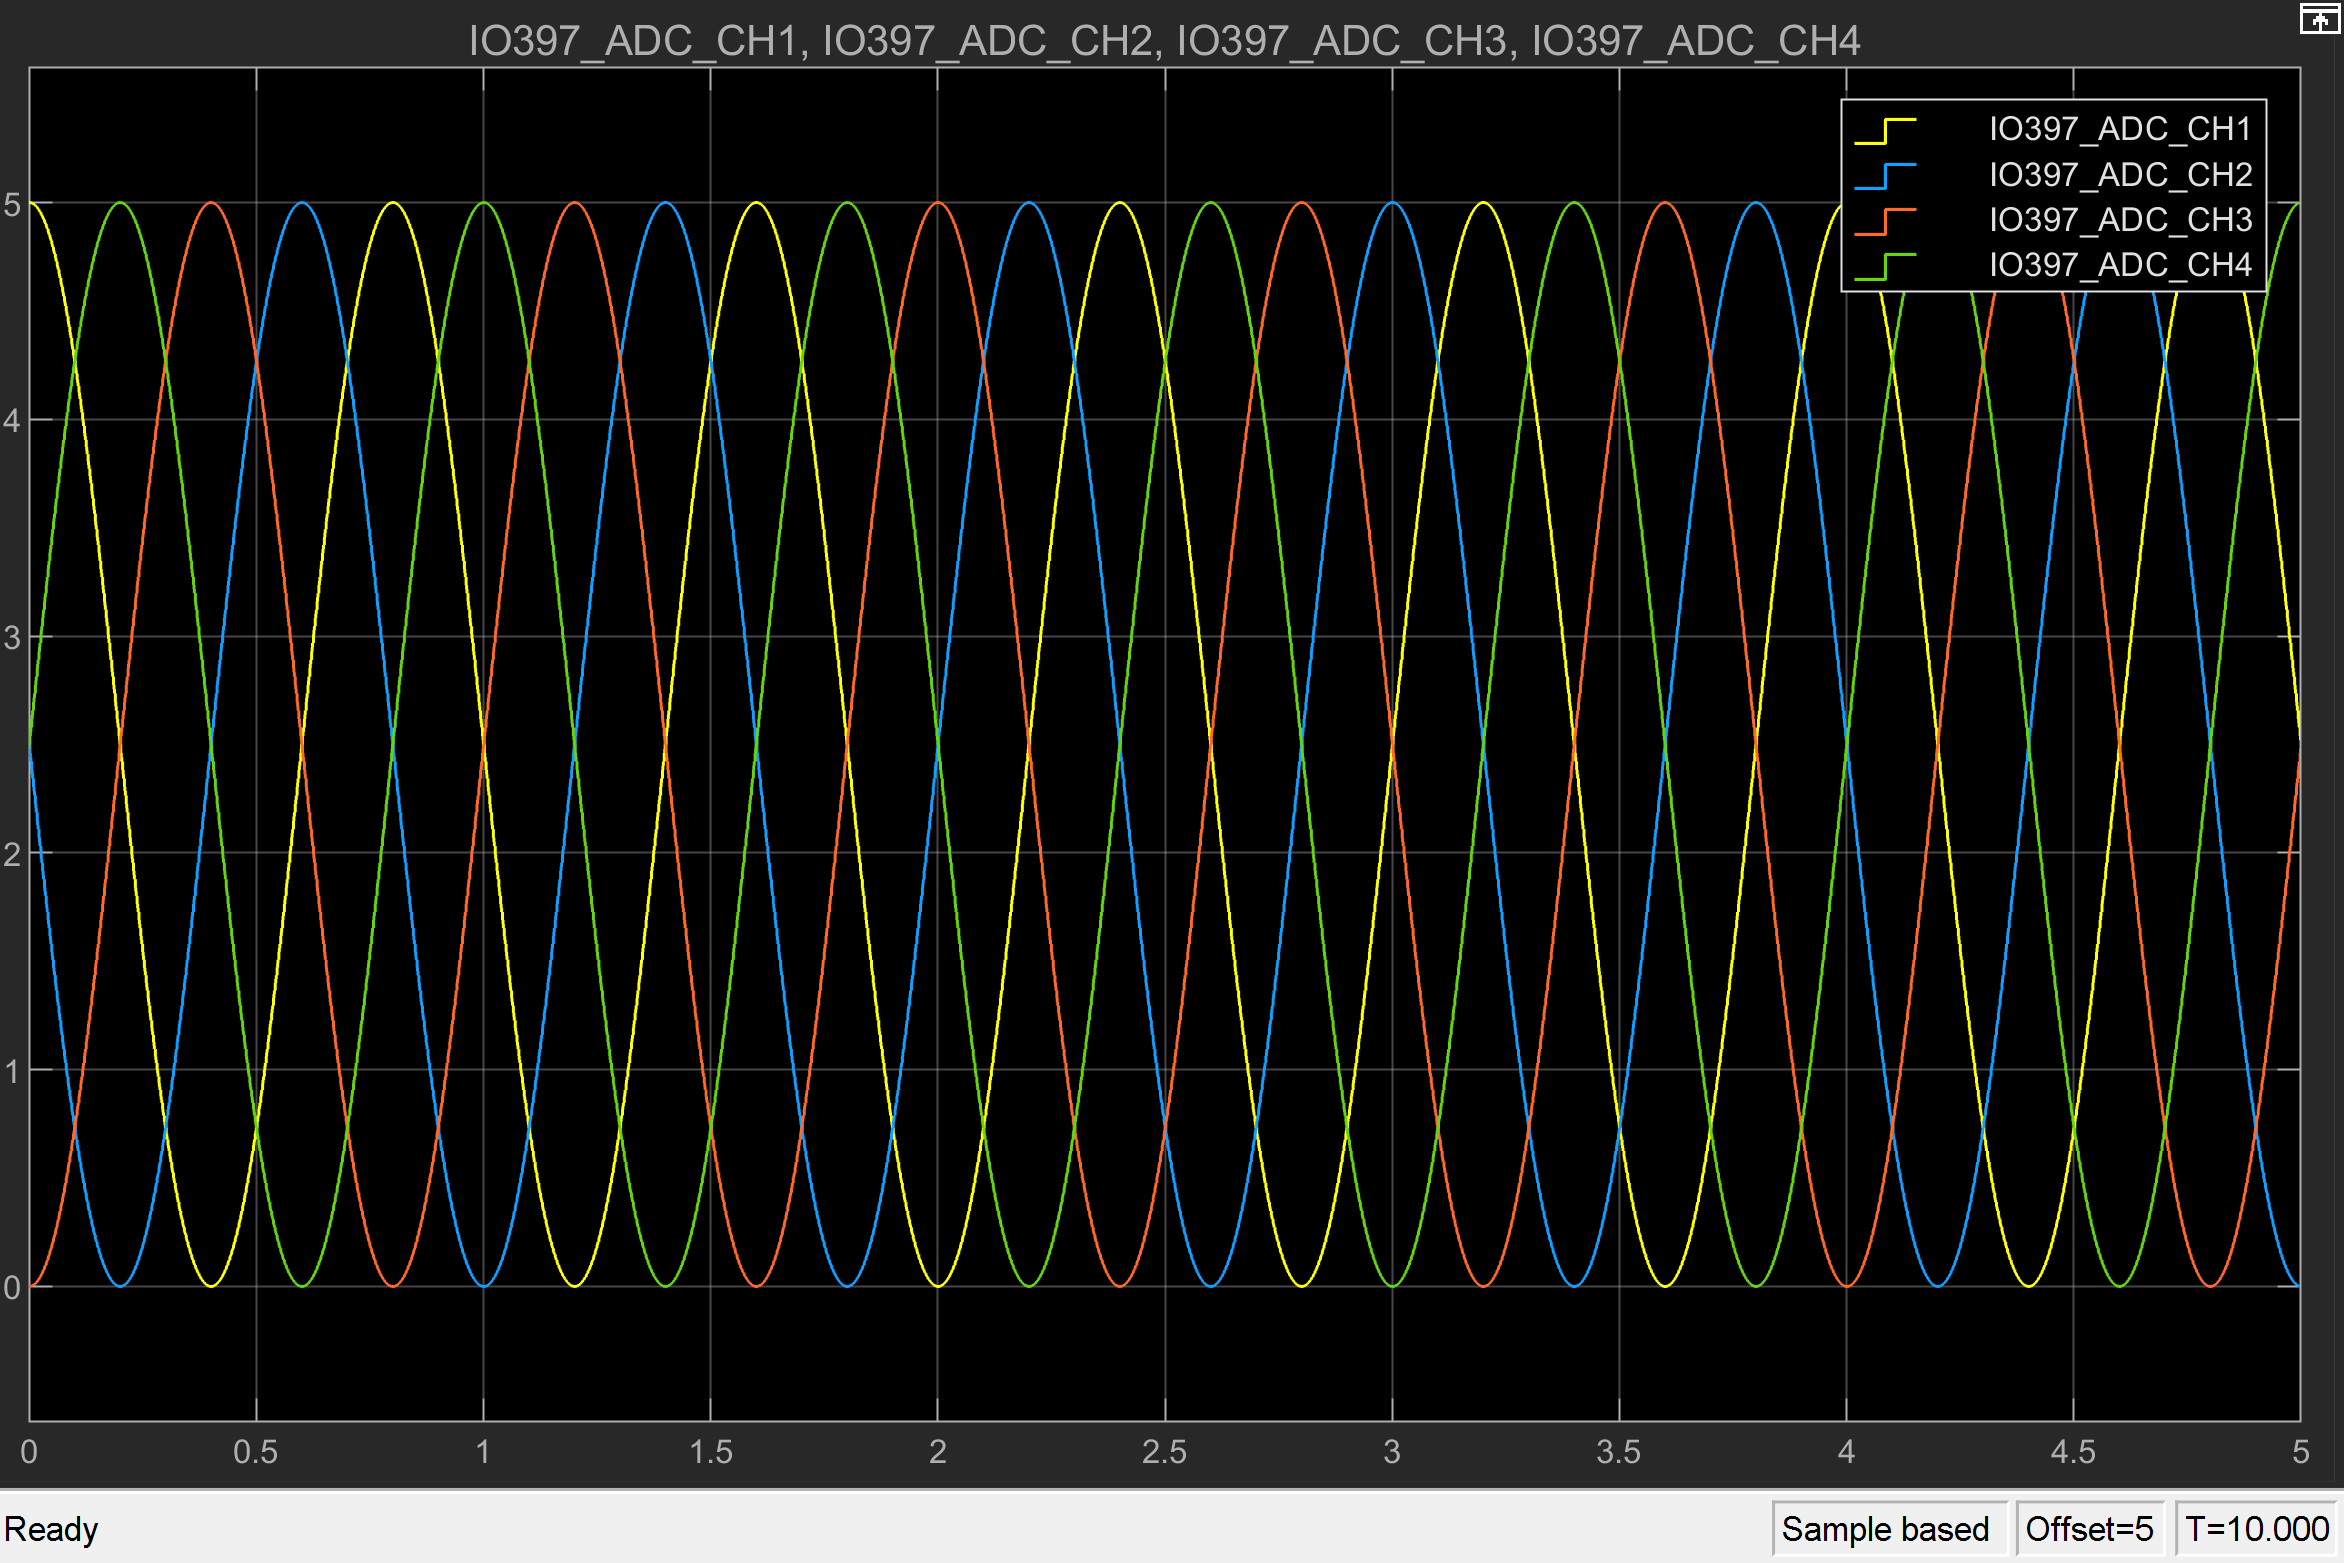

## Additional References

- [IO397-50k module](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_io397_50k)